        BackgroundColor: {1×0 cell}
             BusyAction: {'queue'  'cancel'}
          ButtonDownFcn: {}
               Children: {}
               Clipping: {[on]  [off]}
                  Color: {1×0 cell}
            ContextMenu: {}
              CreateFcn: {}
              DeleteFcn: {}
              EdgeColor: {1×0 cell}
                Editing: {[on]  [off]}
              FontAngle: {'normal'  'italic'}
               FontName: {}
               FontSize: {}
          FontSmoothing: {[on]  [off]}
              FontUnits: {'inches'  'centimeters'  'normalized'  'points'  'pixels'}
             FontWeight: {'normal'  'bold'}
       HandleVisibility: {'on'  'callback'  'off'}
                HitTest: {[on]  [off]}
    HorizontalAlignment: {'left'  'center'  'right'}
            Interpreter: {'none'  'tex'  'latex'}
          Interruptible: {[on]  [off]}
              LineStyle: {'-'  '--'  ':'  '-.'  'none'}
              LineWidth: {}
                 Margin: {}
               

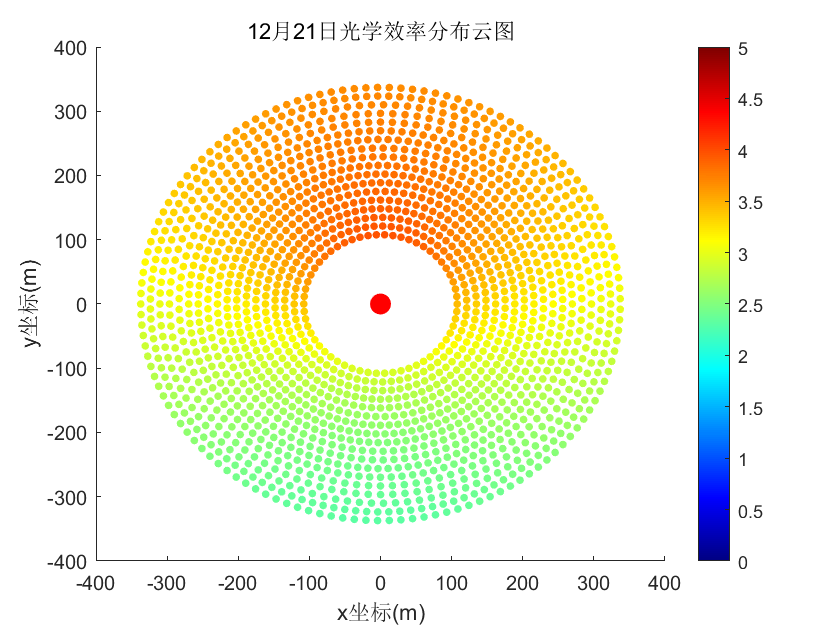

%%光学效率分布云图绘制12个月
for i = 1:12
    S = 15;
    scatter(xy(:,1),xy(:,2),S,mean(eta_all(:,[1:5]+(i-1))*5,2),'filled')
    colormap("jet");
    h = colorbar;
    caxis([0,5]);
    hold on;
    plot(0,0,'ro-','MarkerFaceColor','r','MarkerSize',10);
    set(get(h,'label'));%给颜色栏命名
    xlabel('x坐标(m)');
    ylabel('y坐标(m)');
    text = [num2str(i),'月21日光学效率分布云图'];
    title(text);
    saveas(gca,['eta_MATLAB_',num2str(i),'月21日.png']);
    hold off;
end 